# RoadRunner - Use sensor model by Simulink cosimulation as Observer

# R2024b or later is required

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;
setenv("NO_PROXY", "localhost");

## Start RoadRunner from MATLAB and set Simulink model as observer

When set as observer, Simulink does not need to return vehicle position to RoadRunner 

[addObserver](https://jp.mathworks.com/help/driving/ref/matlab.system.addobserver.html#mw_a615e75e-3e93-4b9d-91fb-dfb6d4099673)  function add Simulink model as observer

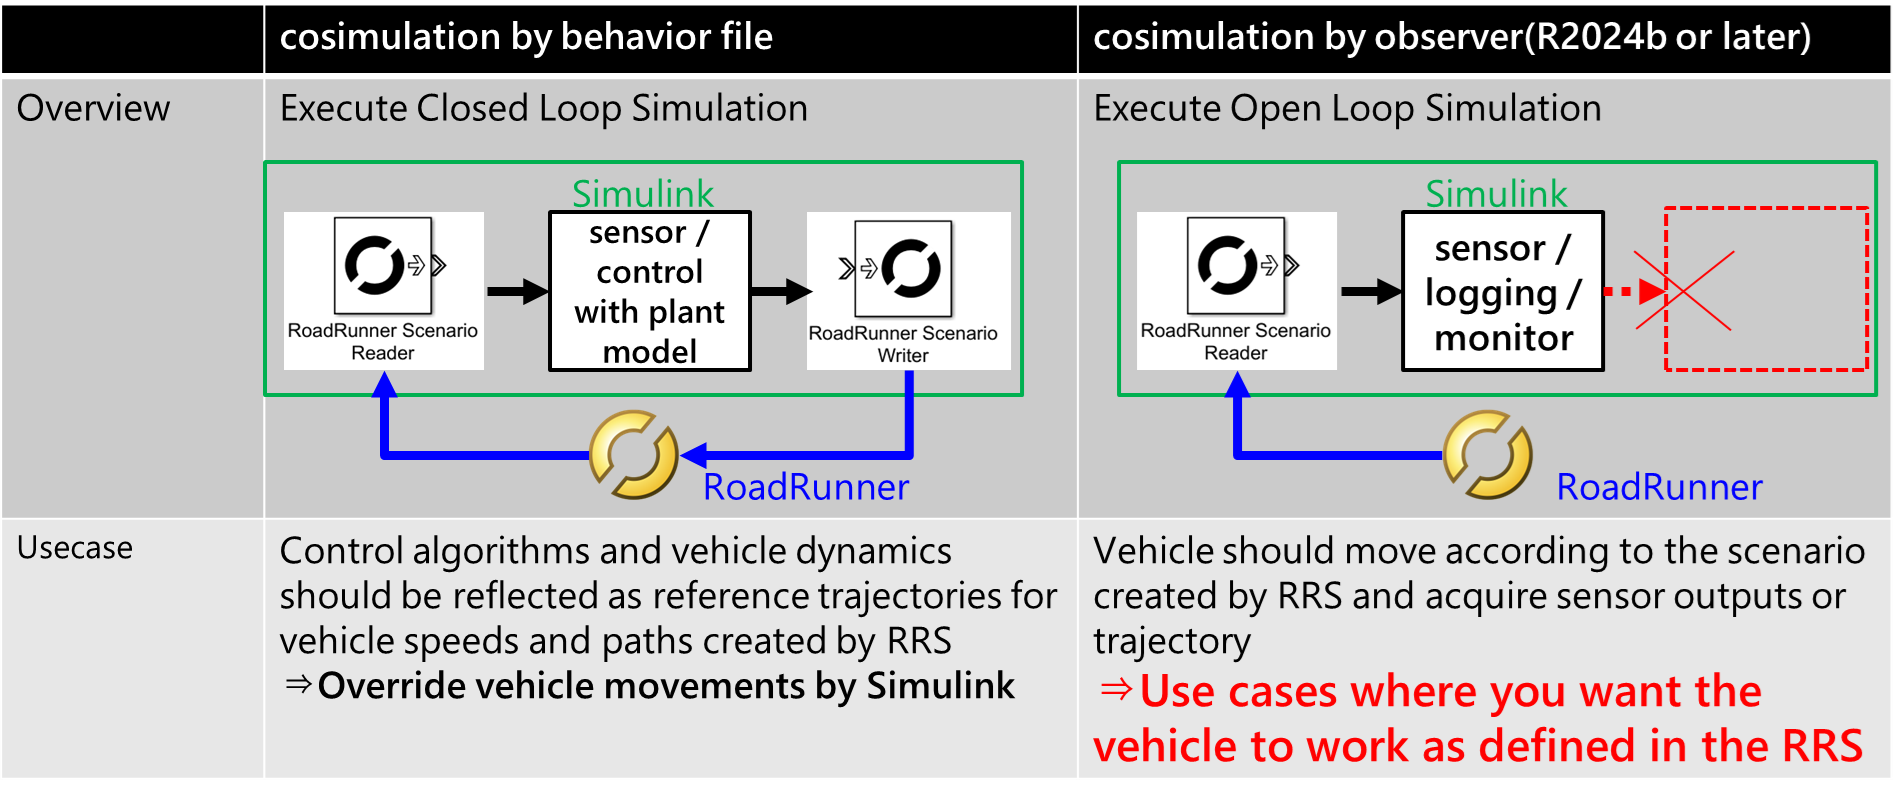

rrApp = roadrunner();

% Start scenario. Scene is linked to scenario, so automatically open scene
rrApp.openScenario("TrajectoryCutIn");

% Align execution step size of RoadRunner and Simulink
simStepSize = 0.1;
rrSim = rrApp.createSimulation();
setRRSCameraMode(rrApp, "follow", actorID=1);
rrSim.set("StepSize", simStepSize);

% Define bus object to get RoadRunner information in Simulink
% To support Reader and Writer blocks, some bus objects must be loaded
loadRoadRunnerBusObject();
load("busDefinitionsForRRSim.mat"); % Read bus object for sensor simulation

% Open Simulink model
model_name = 'SensorSimulinkVehicleObserver';
open_system(model_name);

% Add Simulink model as observer
addObserver(rrSim, "Ego", model_name + ".slx");

% Start simulation
set(rrSim, "PacerStatus", "Off");
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation execution is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end